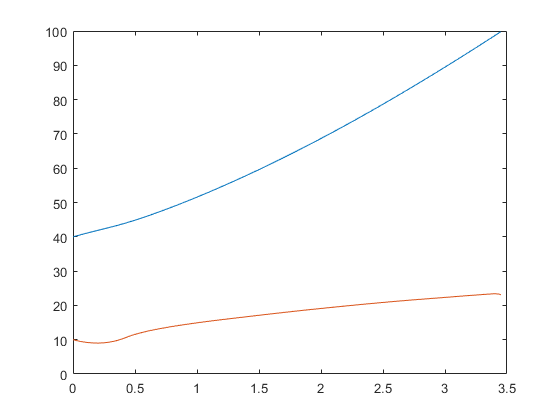

ThrustTable = xlsread('F15_Thrust','Sheet1');
Impulse = cumtrapz(ThrustTable(:, 1), ThrustTable(:, 2));
K = cumtrapz(ThrustTable(:, 1), Impulse);

mass = 1.0565;
g = 9.80655;
burn_time = ThrustTable(end, 1);
v0 = 10;
%s0 = -(v0 * burn_time -g*burn_time^2/2 + K(end)/mass)
s0 = 40; % assume positive (> 0)y

b = (v0 - g * burn_time);
a = -g/2;
c = s0 + v0 * burn_time - g/2 * burn_time^2 + K(end) / mass;
if c < 0
  warning('Infeasible?');
end

temp = (-b + (b^2 - 4*a*c)^.5)/(2*a);
temp2 = (-b - (b^2 - 4*a*c)^.5)/(2*a);

gamma = min(temp, temp2);
if gamma < 0
  gamma = max(temp, temp2);
end
gamma = max(0, gamma);

ThrustAcceleration = griddedInterpolant([-1; ThrustTable(:,1); 100], [0; ThrustTable(:,2); 0] / mass);
ThrustAcceleration = ThrustAcceleration(0:0.01:100);

options = odeset('Events',@events,'Refine',4, 'RelTol', 1e-4, 'AbsTol', 1e-6);
[t,y,te,ye,ie] = ode45(@(t,y) [y(2); ThrustAcceleration(1 + round(t * 100)) - 9.80655], [0 3.45], [s0, v0], options);

plot(t, y)


if ie
  gamma = 0;
  warning('Infeasible')
end
% b = (v0 - g * gamma);
% a = -g/2;
% c = s0 - g/2 * gamma^2 + v0 * gamma + K(end) / mass;
% delta = 0; % element in interval [0, gamma]
% 
% b = v0 + Impulse(end) / mass;
% a = -g/2;
% c = s0 + K(end) / mass + Impulse(end) / mass * (-delta - burn_time);
% tempt = (-b + (b^2 - 4*a*c)^.5)/(2*a);
% tempt2 = (-b - (b^2 - 4*a*c)^.5)/(2*a);
% impact_time = max(tempt, tempt2);

temp3 = v0/g + Impulse(end) / mass /g; % when v(t) = 0
delta_temp = mass / Impulse(end) * (s0 + v0 * temp3 - g/2 * temp3^2 + K(end) / mass + Impulse(end) / mass * (temp3 - burn_time)); % delta when s(t) = v(t) = 0
if 0 <= delta_temp && delta_temp <= gamma
  delta = delta_temp;
  vsquared = 0;
else
  delta = 0;
  b = v0 + Impulse(end) / mass;
  a = -g/2;
  c = s0 + K(end) / mass + Impulse(end) / mass * (-delta - burn_time);
  %a*burn_time^2 + b * burn_time + c > 0, then if statement should never be
  %true
  if (-b + (b^2 - 4*a*c)^.5)/(2*a) >= 3.45
    (-b + (b^2 - 4*a*c)^.5)/(2*a)
    warning('Two valid solutions when delta = 0');
  end
  impact_time = (-b - (b^2 - 4*a*c)^.5)/(2*a);
  v1 = (v0 - g*impact_time + Impulse(end) / mass)^2;
  
  v2 = (v0 - g*(burn_time + gamma) + Impulse(end) / mass)^2;
  
  delta = 0 * (v1 < v2) + gamma * (v2 <= v1);
  vsquared = v1 * (v1 < v2) + v2 * (v2 <= v1);
end  

[delta, vsquared^.5]

ans =     2.6948    3.3040


v2 = [];
b = v0 + Impulse(end) / mass;
a = -g/2;

deltarange = 0:0.01:gamma;

for delta = deltarange
  c = s0 + K(end) / mass + Impulse(end) / mass * (-delta - burn_time);
  impact_time = (-b - (b^2 - 4*a*c)^.5)/(2*a);
  v2 = [v2, (v0 - g*impact_time + Impulse(end) / mass)^2];
end

%plot(0:0.01:gamma, v2.^.5)
[arst, I] = min(v2);
[deltarange(I), arst^.5]

ans =     2.6900    3.9221


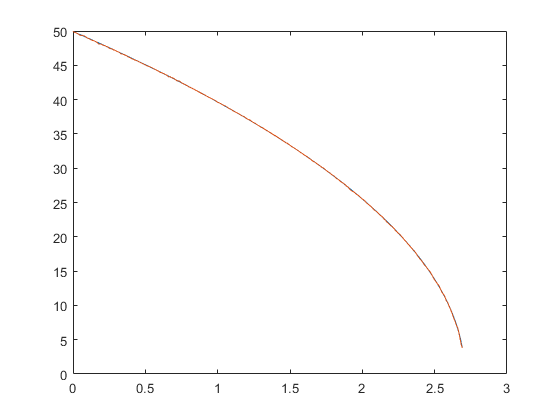

v1 = [];
for delta = deltarange
  [t,y] = ode45(@(t,y) (y(1) > 0 || ThrustAcceleration(1 + round(t * 100)) - 9.80655 > 0) * [y(2); ThrustAcceleration(1 + round(t * 100)) - 9.80655], [0 100], [s0 + v0*delta - g/2 * delta^2, v0 - g * delta], options);
  v1 = [v1, y(end, 2)^2];
end

plot(deltarange, v2.^.5, deltarange, v1.^.5)


[arst, I] = min(v1);
[deltarange(I), arst^.5]

ans =     2.6900    3.8050


clear t, y;
[t,y] = ode45(@(t,y) [y(2); ThrustAcceleration(1 + round(t * 100)) - g], [0 max(impact_time, 5)], [s0 v0]);

% options = odeset('Events',@events,'Refine',4, 'RelTol', 1e-4, 'AbsTol', 1e-6);
% gamma = 0;
% [t,y] = ode45(@(t,y) (y(1) > 0 || ThrustAcceleration(1 + round(t * 100)) - 9.80655 > 0) * [y(2); ThrustAcceleration(1 + round(t * 100)) - 9.80655], [0 100], [s0 + v0*gamma - g/2 * gamma^2, v0 - g * gamma], options);

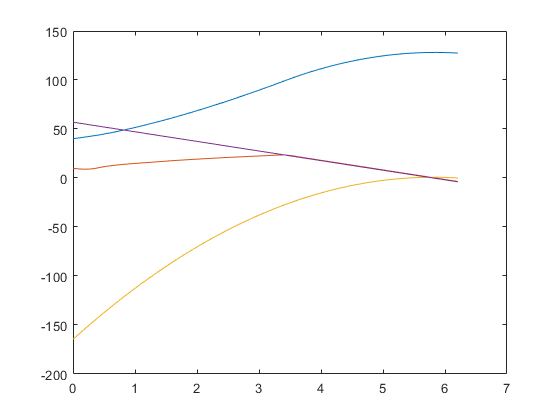

plot(t, y, t, a*t.^2 + b*t + c, t, v0 - g*t + Impulse(end) / mass)

%y(end, 2)

function [value,isterminal,direction] = events(~,y)
    % Locate the time when height passes through zero
    % and stop integration.
    value = y(1) > 0;     % detect height > 0, when height <= 0 gives 0
    isterminal = 1;   % stop the integration
    direction = 0;   % negative direction
end